# Aula 10 - Laboratório de Controle - 2021/1

# Projeto do controlador via realimentação de estados+observador

## Nome: Yuri Rissi Negri

turma= 5;
I=8 ;
Tempo=4;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';

wn=M(I,turma);


arquivo='aula10_R2018.slx';


load dados.mat
i=wn*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));

L=[0;0];
K=[0 0];
RI=0;
Ki=0;
p1=0;
y0=0;


## Atividade 1 - Obtenção do modelo em variáveis de estados e simulação em malha aberta

Modelo em variáveis de estado e função de transferência


$$\dot{x}=Ax+Bu \\
y=Cx\\
\frac{Y(s)}{U(s)}=C(sI-A)^{-1}B$$


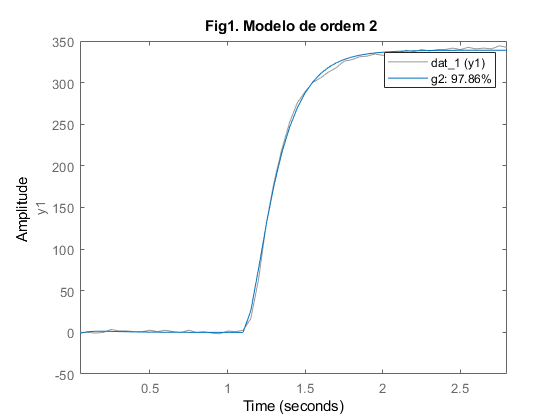

dat=iddata(y1,u1,Ts);
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
g2=tfest(dat_1,2,0);
g2=tf(g2.Numerator,g2.Denominator);
Kp=freqresp(g2,0);
figure
compare(dat_1,g2);title('Fig1. Modelo de ordem 2 ');

[A,B,C,D]=tf2ss(g2.num{1},g2.den{1});
sys=ss(A,B,C,D);

Kp=freqresp(g2,0); 
Ts=0.01; 
s=stepinfo(g2);
ts_ma=s.SettlingTime;
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));
[Y,t]=simula_slx(arquivo,1);
i1=sum(t<2);
y0=mean(Y((i1-10):i1,3));
Tabela1=table(Ref,ts_ma,u0,y0)

Tabela1 = 1×4 table
     Ref       ts_ma     u0      y0  
    ______    _______    __    ______

    1629.9    0.73163    62    1156.7


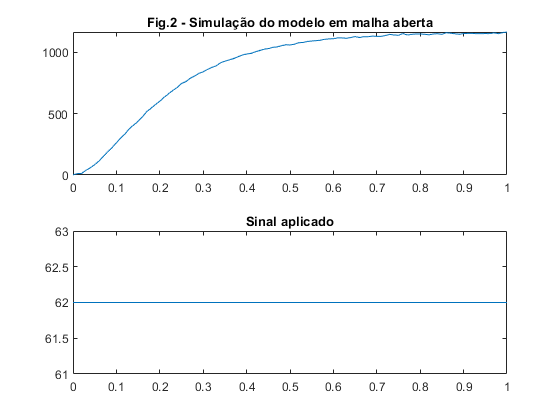

figure
subplot(2,1,1);plot(t,Y(:,[3]));title('Fig.2 - Simulação do modelo em malha aberta');
subplot(2,1,2);plot(t,Y(:,2));title('Sinal aplicado');

1.1 Quantas entradas, quantas saídas, e quantos estados tem o modelo em variáveis de estados armazenado na variável sys? Explicar.

    Pedindo pro matlab imprimir a variável sys, podemos perceber que para o modelo em variáveis de estado vamos ter uma entrada dada por u1, uma saida dada por y1 e dois estados x1 e x2.

## Atividade 2 - Projetar a realimentação de estados e o observador

A figura abaixo mostra a estratégia de controle utilizada. A realimentação de estados da forma $u=Ref-K\tilde{x}$ precisa dos estados, mas apenas a saída $y$ é medida. Para isto se constrói um observador, que envolve calcular o vetor de ganhos $L$ tal que os autovalores de $(A-L*C)$ tenham todos parte real negativa. Com isto, se substitui os estados $x$ por sua estimativa $\tilde{x}$ no controle. O vetor de ganhos da realimentação de estados $K$é calculado tal que os autovalores de $(A-B*K)$sejam os polos do modelo de referência, que tem uma sobreelevação Up e um tempo de estabelecimento iguais aos desejados.

Usar o modelo de referência gesp definido por UPe e tse para definir os polos de malha fechada do controlador por realimentação de estados. Usar valores obtidos dos projetos anteriores.

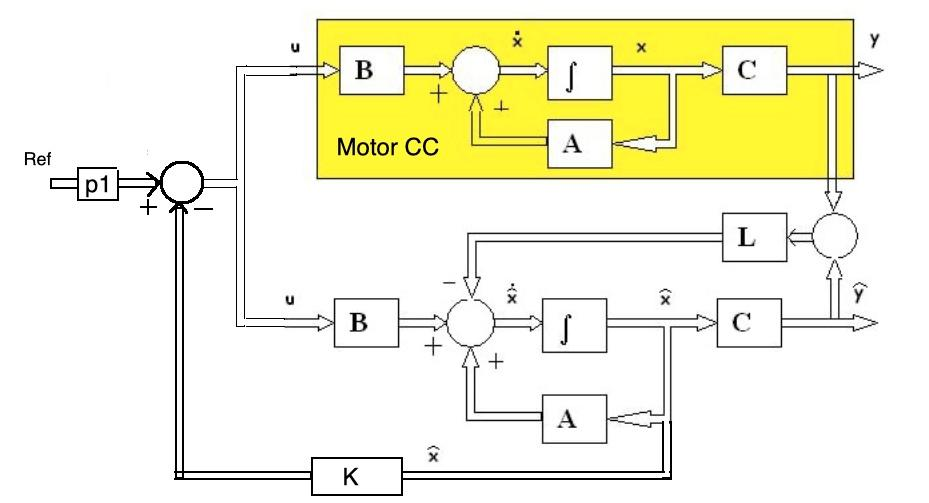

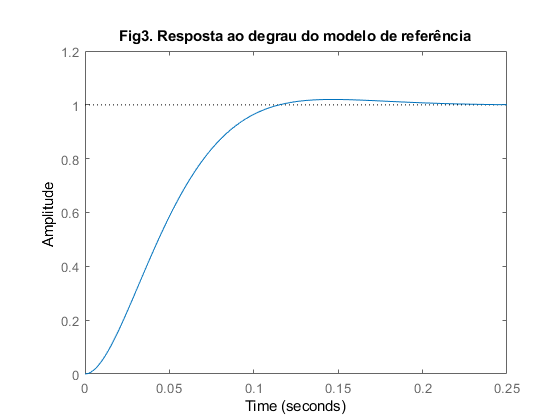

UPe=2; 
tse=0.15 ;
a=log(UPe/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(tse*zeta);
gesp=tf(wn^2,[1 2*zeta*wn wn^2]);
figure;
step(gesp);title('Fig3. Resposta ao degrau do modelo de referência');

Escolhendo agora os polos de malha fechada da realimentação de estados

polos_malhafechada=pole(gesp);

Escolhendo agora os polos do observador de estados, que devem ser n vezes mais rápidos que os polos do controlador da realimentação de estados

n=1;
polos_observador=n*polos_malhafechada;

Calculando as matrizes de ganho da realimentação de estados K e do observador de estados L

K=place(A,B,polos_malhafechada);Kt=K';  
L=place(A',C',polos_observador);L=L';

Tabela com o resumo do projeto:

Tabela_polos_e_ganhos=table(polos_malhafechada,polos_observador,Kt,L)

Tabela_polos_e_ganhos = 2×4 table
    polos_malhafechada    polos_observador      Kt         L    
    __________________    ________________    ______    ________

     -26.667+21.415i      -26.667+21.415i     33.469     0.17632
     -26.667-21.415i      -26.667-21.415i     1085.3    0.014036


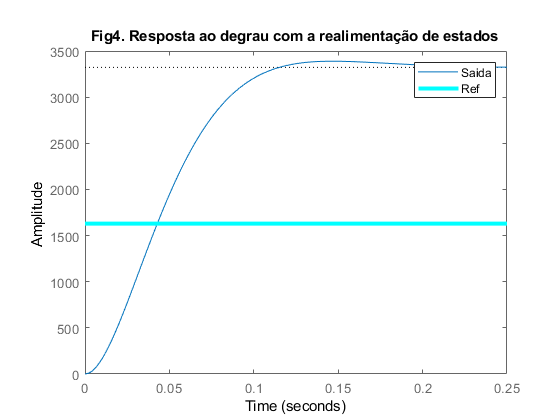

m=ss(A-B*K,B,C,D); 
figure
step(Ref*m);title('Fig4. Resposta ao degrau com a realimentação de estados');
line([0 0.5],[Ref Ref], 'Color','c','LineWidth',3); legend('Saida','Ref');

2.1 Compare e resposta do modelo de referência e a obtida pela realimentação de estados (UP, ts, erro em regime). Dica: a referência a seguir está na Tabela 1.

    Tomando como critério de projeto uma Up = 2 e ts = 0.23, pudemos perceber em uma primeira análise que obtinhamos maiores valores de ts no modelo realimentação de estados. Assim, com o intuito de deslocar os polos do nosso modelo de referência e obter respostas mais rápidas, adotamos na geração da nossa gesp ts = 0.15.

    Dessa forma, ao observar a tabela 1, conseguimos obter uma resposta no modelo de realimentação de estados em que ts = 0.228. Contudo, podemos perceber que a sobreelevação ainda se encontrava ligeiramente maior em relação ao nosso critério.

    Por fim, observando as figuras 3 e 4, podemos perceber que apesar da estabilidade o modelo de realimentação sozinho nos gerou um erro muito grande em relação a referência, o que também pode ser observado na tabela 1, onde nos retorna erro = 0.99. Isso se dá, pelo fato de que nossa entrada será multiplicada pelo ganho K_m, dessa forma, a fim de solucionar tal erro vamos calcular p1 na próxima etapa.

K_gesp=freqresp(gesp,0);
K_m=freqresp(m,0);
tabela_ganhos=table(K_gesp,K_m)

tabela_ganhos = 1×2 table
    K_gesp     K_m  
    ______    ______

      1       2.0386


2.2 Compare os ganhos do modelo de referência e do sistema de MF resultante e calcule p1 para que p1*M(s) tenha o mesmo ganho que gesp. Explique o cálculo.

    Como citado no item anterior, devemos calcular p1 de forma a minimizar o erro. Assim, para que p1*M(s) tenha o mesmo ganho que gesp, devemos ter que p1 * K_m = 1.

    Portanto p1 deverá ser:

    p1 = 1/K_m

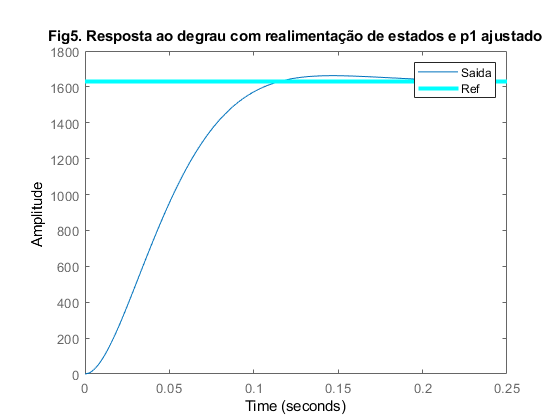

p1=1/K_m; 
figure
step(Ref*p1*m);title('Fig5. Resposta ao degrau com realimentação de estados e p1 ajustado');
line([0 0.5],[Ref Ref], 'Color','c','LineWidth',3); legend('Saida','Ref');

Simule o controlador no modelo do motor (slx). 

p1=0.3/K_m;
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UPp,SettlingTime] = desempenho(Y(:,[2,3]),t,Ref,2);
Tipo={'Especificacoes';'Obtido';};
UP=[UPe;UPp];ts=[tse;SettlingTime];Erro=[0;erro];
Tabela1=table(Tipo,UP,ts,Erro)

Tabela1 = 2×4 table
          Tipo            UP        ts        Erro  
    ________________    ______    _______    _______

    'Especificacoes'         2       0.15          0
    'Obtido'            2.8665    0.22893    0.99104


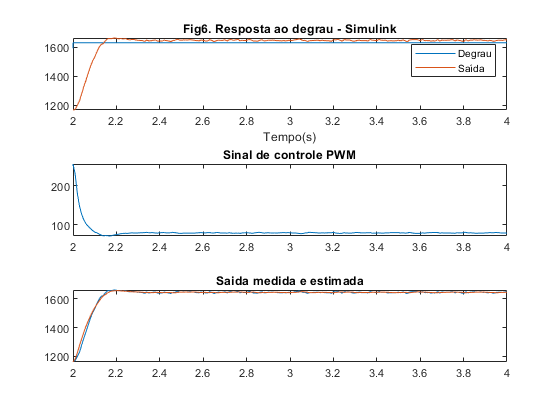


figure
subplot(3,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig6. Resposta ao degrau - Simulink');xlim([2 Tempo]);
subplot(3,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');xlim([2 Tempo]);
subplot(3,1,3);plot(t,Y(:,[3,4]));title('Saida medida e estimada');xlim([2 Tempo]);

2.3 Compare a resposta das figuras 5 e 6, justifique as diferenças, e discuta formas de fazer com que a simulação obtida no motor (fig 6) se aproxime da desejada (modelo de referência), ajustando p1, por exemplo.

    Depois de ajustar p1, podemos perceber que a figura 5 está atendendo a referência. Contudo, em um primeiro momento para o nosso sistema real (motor), representado na figura 6, foi necessário fazer o ajuste de p1, levando em conta agora também o seu efeito sobre o ruído. Por fim, como observado na figura 6, conseguimos fazer com que a simulação obtida no motor se aproxime do modelo de referência.

O ganho K da realimentação de estados e o ganho L do observador de estados podem ser transformados em compensadores C1 e C2 (figura abaixo) aplicados à FT do motor. Basta para isto aplicar a transformada de Laplace  ao sistema em variáveis de estado. isto é feito nas linhas de código abaixo.

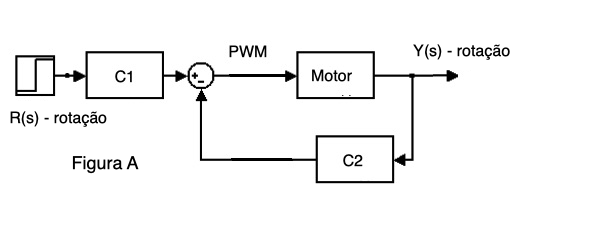

[NC1,DC1]=ss2tf(A-L*C-B*K,B,K,0,1); 
[NC2,DC2]=ss2tf(A-L*C-B*K,L,K,0,1);
C1=1-tf(NC1,DC1)


C1 =
 
  s^2 + 53.33 s + 1170
  --------------------
  s^2 + 86.8 s + 3375
 
Continuous-time transfer function.



C2=tf(NC2,DC2)


C2 =
 
    21.13 s + 454.3
  -------------------
  s^2 + 86.8 s + 3375
 
Continuous-time transfer function.



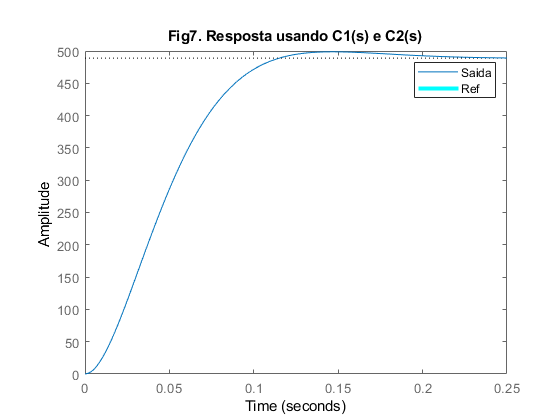

M_re=C1*feedback(g2,C2);
M_re_minima=minreal(M_re);
figure
step(Ref*M_re_minima*p1);
line([0 1],[Ref Ref], 'Color','c','LineWidth',3);
title('Fig7. Resposta usando C1(s) e C2(s)');legend('Saida','Ref');

2.4 Qual a ordem de ?$Y(s)/R(s)$ na Figura B? Qual a ordem da FT M_re_minima? Explique a diferença. Dica: analise os polos e zeros das FTs.

*Obs.: Considerei que o enunciado estava errado e se referia a "Figura A", e que se referia a M_re

    Observando o código, tiramos que M_re é uma FT de ordem 6. Depois de se aplicar a função minreal(M_re), o matlab nos retorna M_re_minima que é de ordem 2. A diferença se dá uma vez que essa função do matlab cancela pares de polos e zeros em M_re retornando uma função de transferência de menor ordem possível sem alterar as características de resposta do modelo original.

Varie os polos do observador tornado-os cada vez mais rápidos que os da  realimentação de malha fechada, e refaça a simulação.

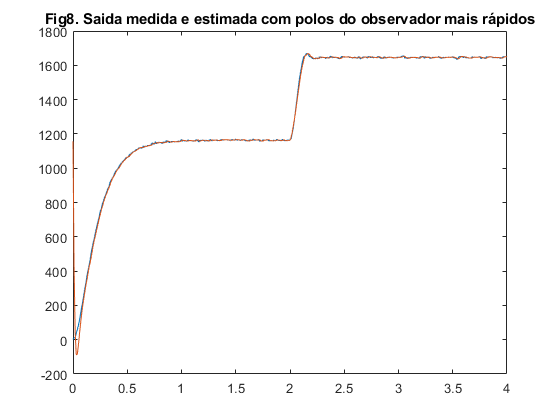

n=2;
polos_observador=n*polos_malhafechada; 
L=place(A',C',polos_observador);L=L';

[Y,t]=simula_slx(arquivo,Tempo);
figure;
plot(t,Y(:,[3,4]));title('Fig8. Saida medida e estimada com polos do observador mais rápidos');

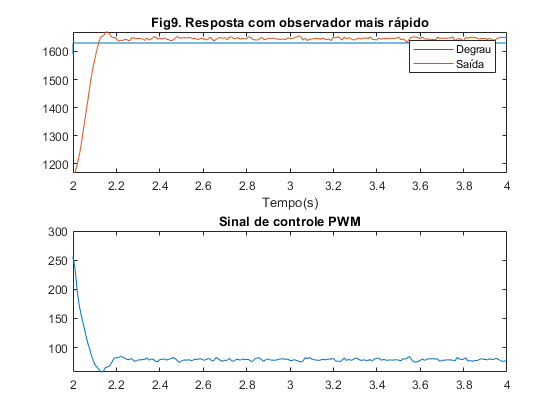

figure
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');xlim([2 Tempo])
title('Fig9. Resposta com observador mais rápido');
subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');xlim([2 Tempo])

2.5 Compare o tempo para o erro da estimativa do estado tender a zero, bem como o comportamento do sinal de controle e da saída, quando varia a localização dos polos do observador.

    Quando variamos o valor de n estamos na verdade afastando os polos do observador da origem, que como vimos em laboratórios passados, quando tomamos polos mais a esquerda no plano complexo S, estamos diminuindo o tempo da resposta do sistema e diminuindo nosso erro estacionário, tendendo a zero. Contudo, estamos aumentando a sobrelevação e deixando nosso sistema mais oscilatório. Dessa forma, deslocamos os polos de tal forma que obtivéssemos os melhores parâmetros sem comprometer nosso sistema.

## Atividade 3 - Realimentação integral de estados

A figura B mostra a configuração da realimentação integral de estados, com o vetor de ganhos K que realimenta os estados originais e o ganho adicional Ki que realimenta o novo estado introduzido pelo integrador. Para esta simulação, faz-se p1=1 e RI=1 (habilita o integrador). 

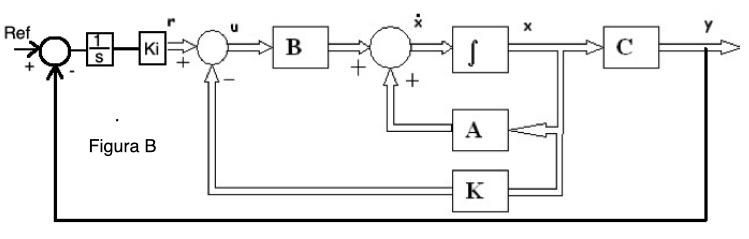

p1=1; 
RI=1; 

Sistema aumentado (adição do integrador)

Aa=[A [0;0]; -C 0]; 
Ba=[B;0];
B2=[0;0;1];
Ca=[C 0];

O terceiro polo p3 deve ser adequadamente escolhido. Teste valores menores e maiores que a parte real dos polos do modelo de referência.

p3=-16.5; 
polos_malhafechada_i=[polos_malhafechada; p3];  
K=place(Aa,Ba,polos_malhafechada_i);
Ki=K(3);
K=[K(1) K(2)];

[Y,t]=simula_slx(arquivo,Tempo);

[erro_i,UP_i,SettlingTime_i] = desempenho(Y(:,[2,3]),t,Ref,2);
Tipo_de_controle={'Especificacoes';'Realimentação estados';'Integral'};
UP=[UPe;UPp;UP_i];ts=[tse;SettlingTime;SettlingTime_i];Erro=[0;erro;erro_i];
Tabela2=table(Tipo_de_controle,UP,ts,Erro)

Tabela2 = 3×4 table
       Tipo_de_controle          UP        ts         Erro  
    _______________________    ______    _______    ________

    'Especificacoes'                2       0.15           0
    'Realimentação estados'    2.8665    0.22893     0.99104
    'Integral'                 1.8532    0.19396    0.020995


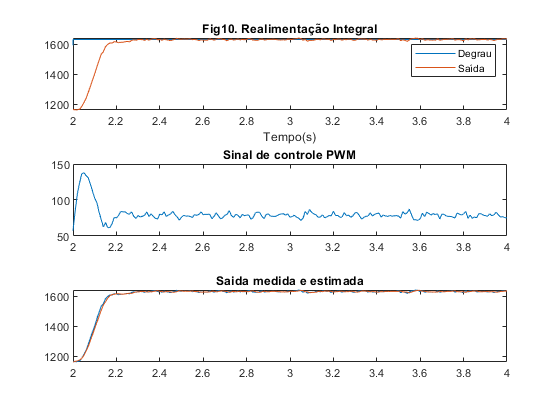


figure;
subplot(3,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');
xlabel('Tempo(s)');title('Fig10. Realimentação Integral');xlim([2 Tempo])
subplot(3,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');xlim([2 Tempo])
subplot(3,1,3);plot(t,Y(:,[3,4]));title('Saida medida e estimada');xlim([2 Tempo])

3.1 Qual o efeito da localização do polo real da realimentacão integral p3 sobre a resposta transitória e sobre o sinal de controle? 

    O polo real p3 da realimentação integral resolve o erro em regime visto anteriormente. Assim ele deve ser alocado considerando seus efeitos na resposta transitória e sobre o sinal de controle. Conforme aproximamos o polo real da origem, vamos ter uma diminuição da oscilação e sobresinal, mas fará com que nossa resposta se torne mais lenta. Já o contrário, se afastarmos demais da origem, geramos uma resposta muito oscilatória. Portanto, variamos p3 de forma a nos gerar o menor valor de ts possível para os nossos polos de malha fechada sem perder a estabilidade do nosso sistema levando-o a oscilação.  

3.2 Compare as Tabelas 2 e 3.

    Comparando os parâmetros da realimentação de estados e da realimentação integral ao observar a tabela 2, podemos perceber que como citado no item anterior, a realimentação integral corrigiu o erro em regime, que era o nosso maior problema. Conseguimos ainda, obter redução considerável nos valores de Up e ts em relação a realimentação de estados, atendendo os nossos critérios de projeto definidos no item 2.1, nos gerando uma boa resposta.

3.3 Compare o projeto do PID com o da realimentacao integral de estados, destacando vantagens/desvantagens dos métodos

    Em teoria, o projeto da realimentação integral de estados nos gera a possibilidade de se obter resultados melhores em relação ao PID, pelo fato de nos dar a liberdade de alterar os polos de malha fechada. Contudo, obtivemos resultados muito próximos ao projeto com PID, mas isso se justifica pela complexidade, caracterizando uma desvantagem, do método utilizado nesse laboratório. Apesar de maior liberdade, também requer um maior entendimento aumentando as chances de erros por parte do projetista. Se quisermos obter ainda melhores resultados no projeto de realimentação integral, deveríamos rever a escolha dos três polos.

    Podemos fazer uma analogia das vantagens/desvantagens quando comparamos esses dois projetos (PID com realimentação integral) com a comparação feita na última aula (entre PID e avanço-atraso), onde um nos dá mais possibilidades a troco de complexidade.

datetime('now')

ans = datetime
   27-Aug-2021 22:38:27


pwd

ans = 'C:\Users\asus1\Desktop\Aula10'